# 卷积码识别分析

    下面开始学习卷积码。

## 1. 编码原理

    卷积码是**非分组码**。卷积码也是码长n中包含着k个信息，但是r=n-k这么长的监督位不仅和当前码字中的n比特有关，还和前面m=N-1个信息段有关。所以一个码字中的监督码元监督着N个信息段。N被称为编码约束度，n*N为编码约束长度。卷积码被记做(n,k,N)，码率还是k/n;

    卷积码也是一种线性码，既然是线性码，就能用一个监督矩阵H和生成矩阵G确定。

    在卷积码中，监督矩阵H是一个有头无尾的半无穷矩阵。半无穷矩阵不便于研究，但是只要研究产生前面nN个码字的的截短监督矩阵就足够了，因为整体监督矩阵可以由截短监督矩阵通过移位和补零生成。通过分析截短监督矩阵，发现只要确定其最后一行，也就是基本监督矩阵，那么监督矩阵也就确定了。$h=\left\lbrack \begin{array}{ccccccccc}
P_N  & O_{n-k}  & P_{N-1}  & O_{n-k}  & P_{N-2}  & O_{n-k}  & \ldotp \ldotp \ldotp  & P_1  & I_{n-k} 
\end{array}\right\rbrack$ $P_i$是(n-k)*k阶矩阵

    生成矩阵G也是一个半无穷矩阵，特点是每一行的结构都相同，只是比上一行向右退后n列。类似的，也有截短生成矩阵，也可以通过截短生成矩阵得到基本生成矩阵。$g=\left\lbrack \begin{array}{ccccccccc}
I_k  & Q_1  & O_k  & Q_2  & O_k  & Q_3  & \ldotp \ldotp \ldotp  & O_k  & Q_N 
\end{array}\right\rbrack$ $Q_i$是k*(n-k)阶矩阵;如果基本生成矩阵给定的话的，可以从已知的信息位得到整个编码序列。

    卷积码的解码方法分为两类：代数解码和概率解码。

    
$$\mathrm{卷积码解码}\left\lbrace \begin{array}{cc}
\mathrm{代数解码} & \mathrm{大数逻辑解码，门限解码}\\
\mathrm{概率解码（最大似然）} & \left\lbrace \begin{array}{c}
\mathrm{序贯解码}\\
\mathrm{维特比算法}
\end{array}\right.
\end{array}\right.$$


结尾卷积码：对于(n,1,m)卷积码，为了使得码字的结束状态与初始全零状态相同，信息序列的最后m个码元必须是全零码元，这样得到的码字序列称为卷积码的结尾码字。

删余卷积码：删余过程实际上是编码器的输出码流中删除一部分码元，被删除码元的个数决定了最终的编码速率。在实现删余时，可以用删余模板来指定传输之前删除那些码元。

卷积码的译码错误概率主要由它的距离特性决定。对于硬判决译码，译码器输入的是二元符号，可以用汉明距离来衡量。对于软判决译码，译码器的操作是基于欧氏距离的，需要用欧氏距离来衡量码字的性能。

卷积码的最小距离定义为码集合中任意两个码字之间的最小汉明距离，也就是码集合中所有非零码字中重量最小的码字重量。全零码字可以作为判定卷积码最小距离的参考序列。

卷积码的最小欧氏距离不仅与码字的网格图结构有关，而且与采用的调制方式有关。

## 2. 编码

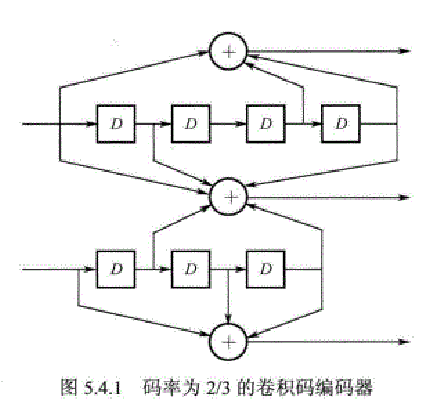

针对这个卷积码编码器进行编码。

%生成编码网格图
clear;
trellis = poly2trellis([5 4],[23 35 0; 0 5 13])
%判断是否是正确的编码网格图
istrellis(trellis)
%编码函数
code = convenc(randi([0 1],1,10),poly2trellis([5,4],[23 35 0; 0 5 13]))
%记住上次的状态，分两次编码
msg = randi([0 1],1,10);
[code1, fstate] = convenc(msg(1:6),trellis)
code2 = convenc(msg(7:10),trellis,fstate)
%一次编码
code3 = convenc(msg,trellis)

## 3. 高斯法解方程分析法

书上介绍了一种高斯法解方程的思路。大体描述一下。

    对分组码进行识别分析最一般的方法莫过于对关于校验矩阵的线性方程组直接求解。该方法需要先估计约束长度，如果能保证采集到的不含误码的分组码的片段序列足够长，则有可能通过直接求解线性方程组得到校验多项式，进而完成分组码的识别。

对于(n,k,N)卷积码。基本监督矩阵h（大小为(n-k)行，(N*n)列）对任意的N*n个比特都存在校验关系。拿到了比特流数据中的N*n个比特C，h*c一定为0的。


$$C=\left\lbrack \begin{array}{cccc}
\mathrm{C1} & \mathrm{C2} & \ldotp \ldotp \ldotp  & \mathrm{Cx}
\end{array}\right\rbrack \;\mathrm{其中C为列}\;\;\;\;$$


如果$C=\left\lbrack \begin{array}{c}
I\\
Q
\end{array}\right\rbrack$那么h就可以写成$h=\left\lbrack \begin{array}{cc}
Q & I
\end{array}\right\rbrack$的形式，$h*C=0$

又 $C^T =\left\lbrack \begin{array}{c}
{\mathrm{C1}}^T \\
{\mathrm{C2}}^T \\
{\mathrm{C3}}^T \\
\ldotp \ldotp \ldotp \\
{\mathrm{Cx}}^T 
\end{array}\right\rbrack$如果$C^T =\left\lbrack \begin{array}{cc}
I & Q^T 
\end{array}\right\rbrack$就可以了。

首先，编写(3,1,3)卷积码的函数。基于以下编码器。

clear;
n = 3;
k = 1;
N = 3;
%msg = [0 1 0 1 0 0 1 1 1 1 0 0 0];
codenum = 10000;
msg = randi([0 1],1,codenum);
trellis = poly2trellis(3,[4,5,7]);
code = convenc(msg,trellis);
codematrix = reshape(code,3,codenum);
codematrix = codematrix'; %这就是编码成的码字,每行一个码字

n1 = 3;
k1 = 1;
N1 = 3;%猜测的卷积码参数
rcode = code(31:end);
x = floor(length(rcode)/(N1*n1));
rcodewordmatrix = reshape(rcode(1:N1*n1*x),N1*n1,x);
rcodewordmatrix = rcodewordmatrix';
x1 = transSimplestRowsGF2V3(rcodewordmatrix);
%这里得到的x1并不能写成上面描述的那样，这个方法不能分析313卷积码

基本监督矩阵g对任意n*N个比特的校验关系都是成立的,由此为依据可以寻找满足$C^T *h=0$的解。并且这个解还是满足一定条件的。基本监督矩阵$h=\left\lbrack \begin{array}{ccccccccc}
P_N  & O_{n-k}  & P_{N-1}  & O_{n-k}  & P_{N-2}  & O_{n-k}  & \ldotp \ldotp \ldotp  & P_1  & I_{n-k} 
\end{array}\right\rbrack$ $P_i$是(n-k)*k阶矩阵

h是n-k行，N*n列的矩阵。

如果在没有错码的条件下，可以通过对矩阵求解找到合适的h矩阵。通过匹配基本监督矩阵形式。

%方法一：遍历求解
h2 = [];
hh = zeros(1,9);
for i1 = 0:1
    hh(1) = i1;
for i2 = 0:1
    hh(2) = i2;
for i3 = 0:1
    hh(3) = i3;
for i4 = 0:1
    hh(4) = i4;
for i5 = 0:1
    hh(5) = i5;
for i6 = 0:1
    hh(6) = i6;
for i7 = 0:1
    hh(7) = i7;
for i8 = 0:1
    hh(8) = i8;
for i9 = 0:1
    hh(9) = i9;    
    if ~any(mod(rcodewordmatrix*hh',2))
        hh
        h2 = [h2; hh];
    end
end
end 
end
end
end
end
end
end
end

hh =      0     0     0     0     0     0     0     0     0


hh =      0     0     0     0     1     1     1     1     0


hh =      0     0     0     1     0     0     0     1     1


hh =      0     0     0     1     1     1     1     0     1


hh =      0     1     1     0     0     1     1     0     1


hh =      0     1     1     0     1     0     0     1     1


hh =      0     1     1     1     0     1     1     1     0


hh =      0     1     1     1     1     0     0     0     0


hh =      1     0     0     0     0     0     1     1     0


hh =      1     0     0     0     1     1     0     0     0


hh =      1     0     0     1     0     0     1     0     1


hh =      1     0     0     1     1     1     0     1     1


hh =      1     1     1     0     0     1     0     1     1


hh =      1     1     1     0     1     0     1     0     1


hh =      1     1     1     1     0     1     0     0     0


hh =      1     1     1     1     1     0     1     1     0


%方法二：遍历求解
hvec = zeros(N1*n1,1);
for i = 0:2^(N1*n1)-1
    v1 = dec2bin(i,N1*n1);
    for i1 = 1:N1*n1
        hvec(i1) = v1(i1)-48;
    end
    %看是否为解
    if ~any(mod(rcodewordmatrix*hvec,2))
       %找到一个符合要求的h。
       %条件一：hvec前面n个不能全都是0，否则的话就不能成为nN个比特有关系了。
       if ~any(hvec(1:n1))
           continue;
       end
       %条件二，对应位置为0
       crelabel = 1;
       for i2 = 1:N1-1 
           v2 = hvec((i2-1)*n1+k1+1:n1*i2);
           if any(v2) %有非零值进
               crelabel = 0;
               break;
           end
       end
       if crelabel
           hvec'
       end        
    end    
end

ans =      1     0     0     0     0     0     1     1     0


ans =      1     0     0     1     0     0     1     0     1


最后得到的这两个向量确实是所求的向量。

试试(2,1,6)卷积码

n = 2;
k = 1;
N = 6;
%msg = [0 1 0 1 0 0 1 1 1 1 0 0 0];
codenum = 10000;%生成的码字个数
msg = randi([0 1],1,codenum);
trellis = poly2trellis(6,[40,47]);%卷积码网络图
code = convenc(msg,trellis);%编码
codematrix = reshape(code,2,codenum);
codematrix = codematrix'; %这就是编码成的码字,每行一个码字
n1 = 2;
k1 = 1;
N1 = 6;%猜测的卷积码参数
rcode = code;
x = floor(length(rcode)/(N1*n1));
rcodewordmatrix = reshape(rcode(1:N1*n1*x),N1*n1,x);
rcodewordmatrix = rcodewordmatrix';
x1 = transSimplestRowsGF2V2(rcodewordmatrix)%初等变换化为行最简形

x1 =      1     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     1     0     1     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     1     0     1     0     1
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     1
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


（2,1,6）卷积码可以得出$C^T =\left\lbrack \begin{array}{cc}
I & Q^T 
\end{array}\right\rbrack$的形式，Q稍加变换就是就是所求的h。

  最后要指出的是，不仅仅是一种卷积码符合上面的猜测。需要多猜测几种常用的卷加码，然后用上面的方法进行计算，最后根据的猜测的结构进行解码，从是否能够恢复信息上进行下一步筛选。

## 4. Walsh-Hadamard分析法

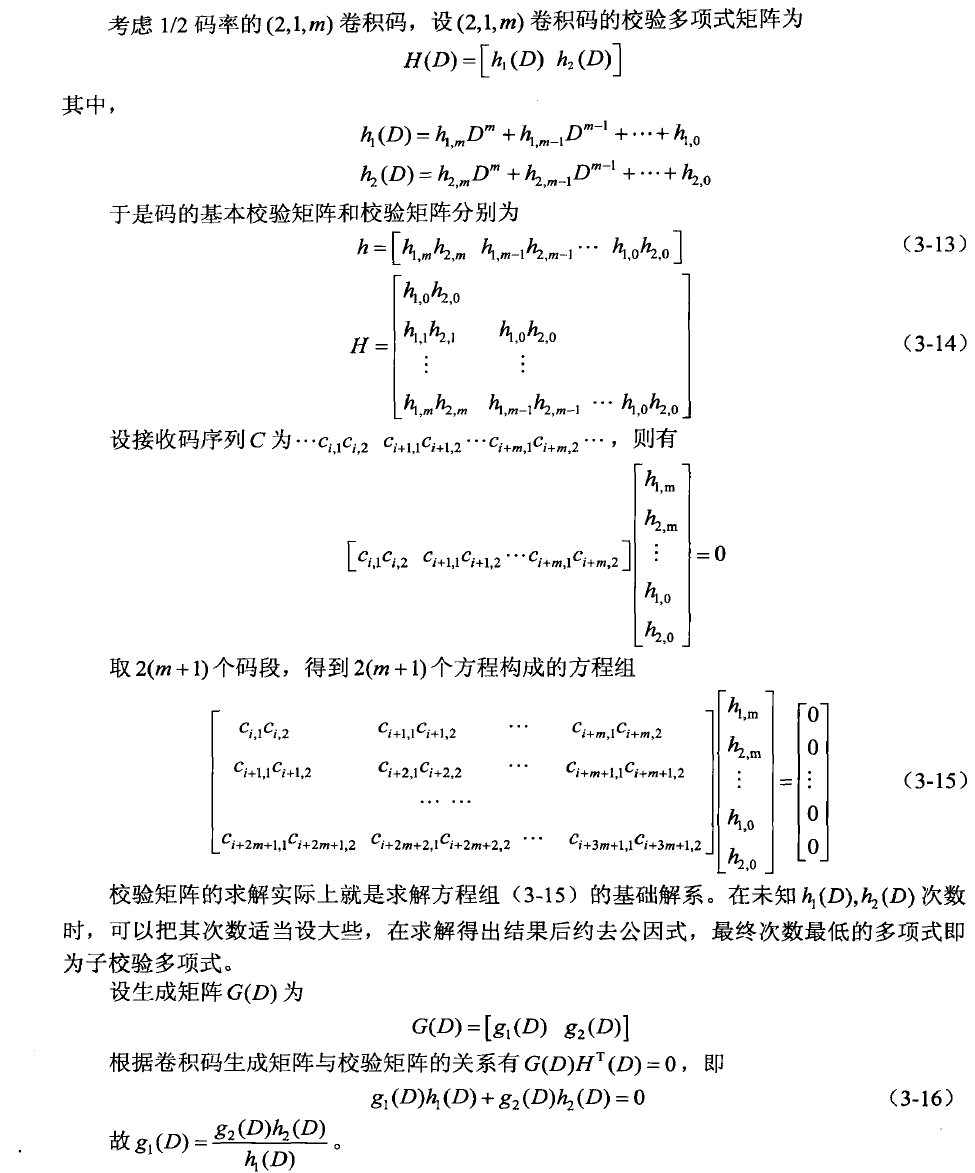

clear;
n = 2;
k = 1;
N = 6;
errorrate = 0.1;
scodenum = 10000;
msg = randi([0 1],1,scodenum);
trellis = poly2trellis(6,[40,47]);
scode = convenc(msg,trellis);
n1 = 2;
k1 = 1;
N1 = 6;%猜测的卷积码参数
%rcode = scode;
rcode = mod(scode + randerr(1,length(scode),floor(errorrate*length(scode))),2);%加上误码

n2 = n1*N1;
rcode_N1len = floor(length(rcode)/n2);
rcodewords = reshape(rcode(1:n2*rcode_N1len),n2,rcode_N1len);
rcodewords = rcodewords';
rcodewordsDEC = zeros(rcode_N1len,1);
for i = 1:n2
    rcodewordsDEC = rcodewordsDEC + rcodewords(:,n2+1-i).*(2^(i-1));
end
%构造向量,统计每个数字出现的个数
rcodewordsDECDistribution = zeros(1,2^n2);
for i = 0:2^n2-1
   rcodewordsDECDistribution(i+1) = sum(rcodewordsDEC==i);
end
%与Hadamard矩阵相乘
x1 = rcodewordsDECDistribution*hadamard(2^n2);
t = 3;
tk = ceil(t*sqrt(rcode_N1len));
x1 = x1(2:end);
loc1 = find(x1>=tk)%找出大与阈值的位置

loc1 =          272        1605        2265        2691        2787        3042        3785        3992


x1(loc1)

ans =    126   132   124   564   124   140   134   126


loc2 = find(x1==max(x1))%找出值最大的位置

loc2 = 2691

上面的程序多运行几次，调整一下误码率，发现得到的大于阈值的解会有很大的变化，但是最大值的位置‘2691 =101010000011’这个解一直都在。对于（2、1、6）这个卷积码，基本监督矩阵就是1*12的矩阵，所以只需要挑选出一个解。hadamard法抗噪声能力较强。

## 5. 基于BM的快速合冲法

这个方法没有理解，暂时跳过。

## 6. 改进的欧几里得算法

首先是欧几里得算法。

% (2,1,6)卷积码
clear;
n = 2;
k = 1;
N = 6;
errorrate = 0;
scodenum = 10000;
msg = randi([0 1],1,scodenum);
%trellis = poly2trellis(6,[40,47]);
trellis = poly2trellis(6,[54,47]);

scode = convenc(msg,trellis);
%rcode = scode;
rcode = mod(scode + randerr(1,length(scode),floor(errorrate*length(scode))),2);%加上误码

L = 100;
c = rcode(1:2*L);%要求送入的是起始码字的第1比特
%c = rcode(101:100+2*L);%码字起点
%c = [1 1 0 1 1 0 0 1 0 0 1 0 1 0 0 0 1 1 1 1 0 0 0 1 0 0 0 0 0 1 1 1 1 1 0 0 0 1 1 1 0 0 1 0 1 1 0 1 0 1];
%c = [1 1 0 1 0 1 0 0 0 0 1 1 1 0 0 1 1 0 1 1 0 0 1 1 0 0 0 0 1 1 1 0 1 0 0 1 1 0 0 1 1 1 0 1 0 1 0 0 1 0];
%c1 = [1 0 1 1 0 0 0 0 0 0 0 0 1 0 0 1 1 1 1 1 0 1 0 1 0 1 0 1 1 0 1 0 1 1 0 0 1 1 0 1 1 0 1 1 0 0 1 1 1 1 1 0 0 0 0 1 1 0 1 0 0 1 0 0 1 0 1 1 0 0 0 1 0 1 1 0 0 0 1 0 0 0 1 1 0 1 0 0 0 1 0 1 0 1 1 1 1 0 0 0];
%c2 = [1 0 1 0 1 0 0 0 1 0 0 0 1 0 0 0 0 0 0 1 1 0 1 1 0 0 0 0 1 1 1 0 1 1 1 0 1 1 1 0 1 0 1 1 0 0 1 1 0 0 1 1 1 1 0 0 1 0 0 0 0 1 1 1 0 1 0 0 1 0 0 1 1 1 0 1 0 0 1 1 0 1 0 0 0 0 0 0 0 0 1 1 1 0 1 0 1 0 1 1];


c = gf(reshape(c,2,L));
maxIter = 50;%50是一个大概的数，和递归次数有关。
g = gf(zeros(2,L,maxIter));
r = gf(zeros(maxIter,L));
%初始化
g(2,L,1) = 1;
g(1,L,2) = 1;
r(1,:) = c(1,:);
r(2,:) = c(2,:);
%r(1,:) = c1;
%r(2,:) = c2;

%下面开始递归计算
for i = 3:maxIter
    %去掉开头的零
    [qt,rt] = deconv(r(i-2,:), delStartZeros(r(i-1,:)));
    %将rt保留最后25位，存储在r(i)里面
    %防止rn长度不是25
    if(length(rt)~=L)
        disp('error, code = 1.');
        break;
    end
    r(i,:) = rt;
    % g2t
    g1t = conv(qt, g(1,:,i-1));
    g(1,:,i) = g(1,:,i-2) + keepveclen(g1t,L);
    % g1t
    g2t = conv(qt, g(2,:,i-1));
    g(2,:,i) = g(2,:,i-2) + keepveclen(g2t,L);
    
    disp('---------------------------------');
    i
    g(:,:,i)
    rt
    qt
    
    if calcDeg(rt) < 12
        break;
    end
end

---------------------------------


i = 3

 
ans = GF(2) array. 
 
Array elements = 
 
  列 1 至 33

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 34 至 66

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 67 至 99

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 100

   1
   1



 
rt = GF(2) array. 
 
Array elements = 
 
  列 1 至 33

   0   0   1   1   0   0   0   0   0   0   0   1   1   1   1   1   0   1   1   0   0   0   1   0   0   1   1   1   0   1   1   0   0

  列 34 至 66

   1   1   0   0   0   1   0   1   0   1   0   1   1   0   0   1   1   1   1   0   1   1   1   1   0   0   0   0   0   1   0   0   1

  列 67 至 99

   0   0   1   0   1   1   1   0   0   0   1   1   1   0   0   1   1   1   0   1   0   0   0   1   1   1   0   0   1   0   0   0   0

  列 100

   1



 
qt = GF(2) array. 
 
Array elements = 
 
   1



---------------------------------


i = 4

 
ans = GF(2) array. 
 
Array elements = 
 
  列 1 至 33

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 34 至 66

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 67 至 99

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0

  列 100

   0
   1



 
rt = GF(2) array. 
 
Array elements = 
 
  列 1 至 33

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 34 至 66

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 67 至 99

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1

  列 100

   1



 
qt = GF(2) array. 
 
Array elements = 
 
   1   0   1



gf2vecgcd(g(1,:,8),g(2,:,8))

 
ans = GF(2) array. 
 
Array elements = 
 
   1



构造1/2卷积码。

clear;
n = 2;
k = 1;
N = 6;
errorrate = 0;
scodenum = 10000;
msg = randi([0 1],1,scodenum);
trellis = poly2trellis(6,[40,47]);
%trellis = poly2trellis(6,[54,47]);

scode = convenc(msg,trellis);
%rcode = scode;
rcode = mod(scode + randerr(1,length(scode),floor(errorrate*length(scode))),2);%加上误码

c = reshape(rcode(101:302),2,101);
c1 = c(1,:);
c2 = c(2,:);
c3 = zeros(1,101);
c3(1) = 1;%构造三个输入向量
%clear;
%书上的例子，采用(2,1,8)卷积码构造的数据
% g1(x) = 1 + x^0 + x^2 + x^3 + x^5 + x^7 + x^8
% g2(x) = 1 + x^2 + x^3 + x^4 + x^8
% c1 = [1 0 0 1 1 1 1 1 1 1 1 0 0 0 0 1 0 0 1 0 0 0 0 0 0 0 1 0 0 0 1];
% c2 = [1 0 0 0 1 0 1 1 0 1 0 1 0 1 1 1 0 1 1 1 0 1 0 0 1 1 1 0 0 0 1];
% c3 = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];


N = 100;%最高次数，码流31个比特
maxiternum = 50;
L = 5;

% r第一个维度代表
%  第二个维度代表
%  第三个维度是
r = gf(zeros(3,101,maxiternum));
T = 1;
r(1,:,1) = gf(c1);
r(2,:,1) = gf(c2);
r(3,:,1) = gf(c3);
K = 1;
T = zeros(1,maxiternum);%T不知道循环多少次，产生多少值

for K = 1:maxiternum
    %寻找r(j,1:3,..)中次数最低的项，同次数选前面的。
    T(K) = 1;
    mindeg = calcDeg(r(1,:,K));
    for i = 2:3
        tmp = calcDeg(r(i,:,K));
        if mindeg > tmp
            T(K) = i;
            mindeg = tmp;
        end
    end
    if mindeg <= L
        disp('找到符合条件的K');
        K
        dx = r(T(K),:,K)
        break;
    end
    %最小次数直接赋值下一次循环
    r(T(K),:,K+1) = r(T(K),:,K);
    
    %找到了次数最小的项
    for i = 1:3
        if i == T(K)
            continue;
        end
        %r(T(k),:,K)是除数
        R = r(T(K),:,K);
        for i2 = 1:length(R)
            if R(i2)==1
                break;
            end
        end
        R = R(i2:end);
        [q, rn] = deconv(r(i,:,K),R);
        %防止rn长度不是31
        if(length(rn)~=101)
            disp('error, code = 1.');
            break;
        end
        r(i,:,K+1) = rn;
    end
end

找到符合条件的K


K = 10

 
dx = GF(2) array. 
 
Array elements = 
 
  列 1 至 33

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 34 至 66

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

  列 67 至 99

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1

  列 100 至 101

   1   0



g = zeros(3,101);
g(4-T(K),101) = 1;
g = gf(g);

for K1 = 1:K-1
    K2 = K-K1;
    tmp = gf(zeros(1,201));
    for i = 1:3
        if i==T(K2)
            continue;
        end
        tmp = tmp + conv(r(i,:,K2),g(4-i,:));        
    end
    %tmp
    %去除前面的0
    R1 = r(T(K2),:,K2);
    for i2 = 1:length(R1)
        if R1(i2)==1
            break;
        end
    end
    R1 = R1(i2:end);
    [q,rtmp] = deconv(tmp,R1);
    qlen = length(q);
    if qlen <= 101
        g(4-T(K2),:) = gf(zeros(1,101));
        g(4-T(K2),102-qlen:end) = q;
    else
        g(4-T(K2),:) = q(qlen-100:end);
    end
    g(:,80:101)   
end

 
ans = GF(2) array. 
 
Array elements = 
 
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1

 
ans = GF(2) array. 
 
Array elements = 
 
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1

 
ans = GF(2) array. 
 
Array elements = 
 
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

 
ans = GF(2) array. 
 
Array elements = 
 
   0   0   0   0   0

clear;
%书上的例子，采用(2,1,8)卷积码构造的数据
% g1(x) = 1 + x^1 + x^2 + x^3 + x^6
% g2(x) = 1 + x^2 + x^3 + x^5 + x^6
c1 = [1 1 1 1 1 1 1 0 1 0 1 0 1 1 1 0 1 0 1 0 0 1 1 1 0 1 0 1 1 1 0 1 0 0 0 0 0 0 1 1 1 1 1 0 1 0 1 1 0 0 0 1 1 1 1 0 0 0 0 1 1 1 0 1 0 1 0 0 0 0 1 1 0 1 1 1 1 1 0 0 1 0 1 1 0 0 0 0 1 0 1 0 0 0 0 1 0 0 0 1];
c2 = [1 0 1 0 1 1 0 0 1 0 0 1 0 0 1 0 1 1 0 1 1 1 0 0 0 0 1 0 1 1 1 1 0 1 0 1 0 1 1 0 0 1 0 1 0 0 1 0 1 0 1 0 1 1 0 0 1 0 0 1 1 0 1 1 0 1 0 1 1 0 0 0 1 1 1 0 1 0 1 1 1 1 0 1 0 1 1 0 1 0 1 0 1 0 1 0 1 1 0 1];
c3 = [1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
N = 99;%最高次数，码流100个比特
maxiternum = 50;
L = 10;

% r第一个维度代表
%  第二个维度代表
%  第三个维度是
r = gf(zeros(3,100,maxiternum));
T = 1;
r(1,:,1) = gf(c1);
r(2,:,1) = gf(c2);
r(3,:,1) = gf(c3);
K = 1;
T = zeros(1,maxiternum);%T不知道循环多少次，产生多少值

for K = 1:maxiternum
    %寻找r(j,1:3,..)中次数最低的项，同次数选前面的。
    T(K) = 1;
    mindeg = calcDeg(r(1,:,K));
    for i = 2:3
        tmp = calcDeg(r(i,:,K));
        if mindeg > tmp
            T(K) = i;
            mindeg = tmp;
        end
    end
    if mindeg <= L
        disp('找到符合条件的K');
        K
        dx = r(T(K),:,K)
        break;
    end
    %最小次数直接赋值下一次循环
    r(T(K),:,K+1) = r(T(K),:,K);
    
    %找到了次数最小的项
    for i = 1:3
        if i == T(K)
            continue;
        end
        %r(T(k),:,K)是除数
        R = r(T(K),:,K);
        for i2 = 1:length(R)
            if R(i2)==1
                break;
            end
        end
        R = R(i2:end);
        [q, rn] = deconv(r(i,:,K),R);
        %防止rn长度不是31
        if(length(rn)~=100)
            disp('error, code = 1.');
            break;
        end
        r(i,:,K+1) = rn;
    end
end

g = zeros(3,100);
g(4-T(K),100) = 1;
g = gf(g);

for K1 = 1:K-1
    K2 = 11-K1;
    tmp = gf(zeros(1,199));
    for i = 1:3
        if i==T(K2)
            continue;
        end
        tmp = tmp + conv(r(i,:,K2),g(4-i,:));        
    end
    %去除前面的0
    R1 = r(T(K2),:,K2);
    for i2 = 1:length(R1)
        if R1(i2)==1
            break;
        end
    end
    R1 = R1(i2:end);
    [q,rtmp] = deconv(tmp,R1);
    qlen = length(q);
    if qlen <= 100
        g(4-T(K2),:) = gf(zeros(1,100));
        g(4-T(K2),101-qlen:end) = q;
    else
        g(4-T(K2),:) = q(qlen-99:end);
    end
    g   
end


经过查阅文献，还是无法得到正确的结果，感觉书上和文献的算法和例子都对不上，花费了一天的时间，没有成功，稍后再问问。

## 7. 综合分析法

clear;
n = 2;
k = 1;
N = 6;
errorrate = 0;
scodenum = 500000;
msg = randi([0 1],1,scodenum);
trellis = poly2trellis(6,[40,57]);
scode = convenc(msg,trellis);
rcode = mod(scode + randerr(1,length(scode),floor(errorrate*length(scode))),2);%加上误码

n2 = 2520;%每行2520个数据
rcode_N1len = floor(length(rcode)/n2);
rcodewords = reshape(rcode(1:n2*rcode_N1len),n2,rcode_N1len);
rcodewords = rcodewords';
rcodewords2 = rcodewords(:,1:64);
rsim = transSimplestRowsGF2V3(rcodewords2)

rsim =      1     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0

可见rsim从12列开始有校验101010000011。所以可以做如下合理猜测：2*6,6*2,4*3,3*4. 可以依次进行实验。比如，依次调整码字起始位置，看看判断出来的码字起始位置都在哪里。

startbit = 1;
rcode = rcode(startbit+1:end);
n2 = 2520;%每行2520个数据
rcode_N1len = floor(length(rcode)/n2);
rcodewords = reshape(rcode(1:n2*rcode_N1len),n2,rcode_N1len);
rcodewords = rcodewords';
rcodewords2 = rcodewords(:,1:64);
rsim = transSimplestRowsGF2V3(rcodewords2)

rsim =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     1     0     1

clear;
n = 3;
k = 1;
N = 3;
%msg = [0 1 0 1 0 0 1 1 1 1 0 0 0];
errorrate = 0;
codenum = 100000;
msg = randi([0 1],1,codenum);
trellis = poly2trellis(3,[4,5,7]);
scode = convenc(msg,trellis);
rcode = mod(scode + randerr(1,length(scode),floor(errorrate*length(scode))),2);%加上误码

startbit = 5;
rcode = rcode(startbit+300:end);
n2 = 2520;%每行2520个数据
rcode_N1len = floor(length(rcode)/n2);
rcodewords = reshape(rcode(1:n2*rcode_N1len),n2,rcode_N1len);
rcodewords = rcodewords';
rcodewords2 = rcodewords(:,1:64);
rsim = transSimplestRowsGF2V3(rcodewords2)

rsim =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     1     1     0     0     0     0     0     0     0     0

理解：rsim的01结构如下：

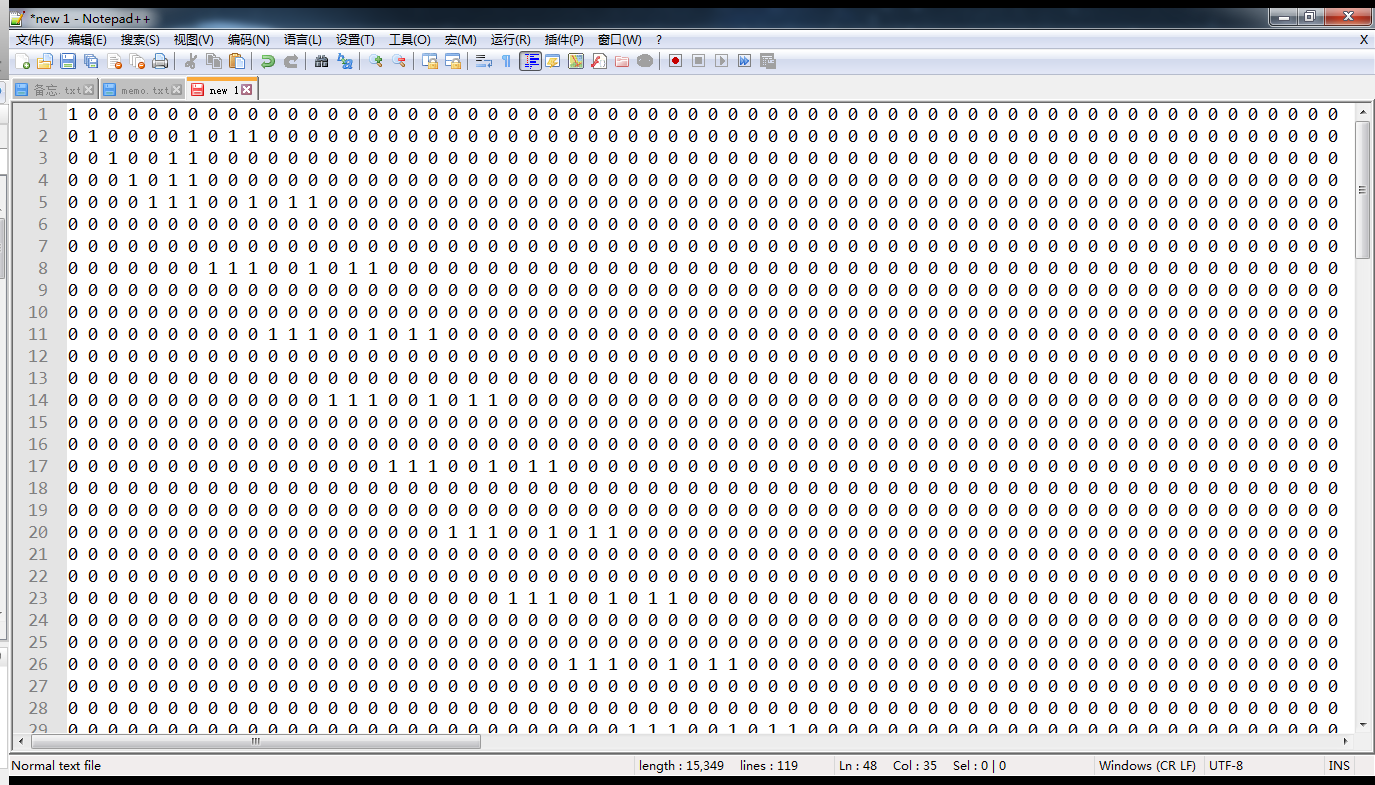

找出可能的校验列。

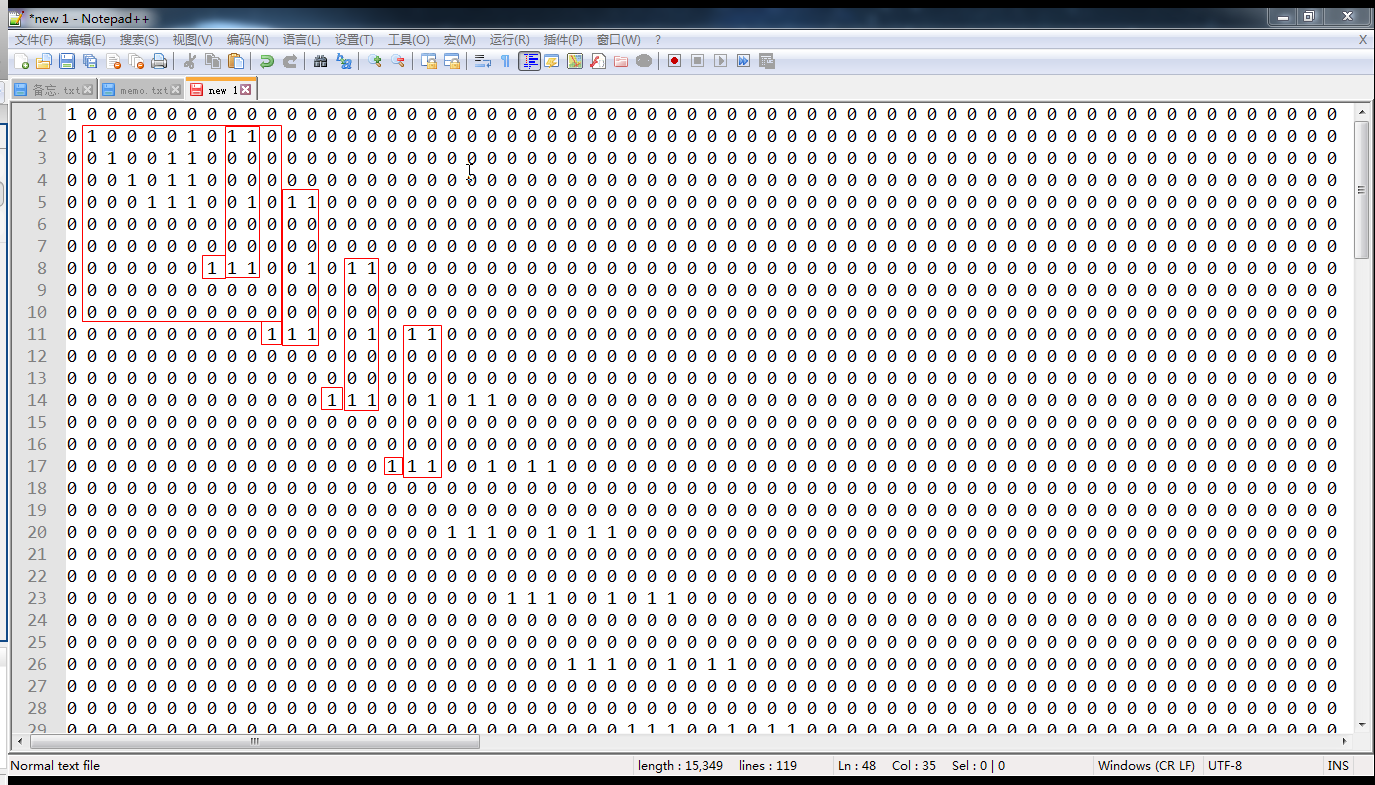

看出码长为3，信息位为1. 校验序列是[100000110]和[100100101]

[100000110] 每隔3bit进行拆分变成[101 001 000]，

[100100101] 每隔3bit进行拆分变成[111 000 001]

校验矩阵即$\left\lbrack \begin{array}{ccc}
1+D^2  & 1 & 0\\
1+D+D^2  & 0 & 1
\end{array}\right\rbrack$,由$G*H^T =0$可得系统循环码的生成矩阵$G=\left\lbrack \begin{array}{ccc}
1 & 1+D^2  & 1+D+D^2 
\end{array}\right\rbrack$

关于非系统循环码

此外，书上还给出了非系统循环码的识别，没有太懂，而且对于非系统循环码来说，校验矩阵和生成矩阵不是一对一的关系，识别起来要经过多次的比对和测试，比较麻烦。

## End:自编函数

function [gys] = gf2vecgcd(s1,s2)
%   s1次数大于s2的次数
%   求GF(2)上两个多项式的公因式，用辗转相除法
%   如果s2全零，s1即为所求
    if any(s2,'all')==false
        %disp('s2全零');
        gys = s1;
        return;
    else
        %去掉头上的非零
        for i = 1:length(s1)
            if s1(i)==1
                break;
            end
        end
        s1 = s1(i:end);
        for j = 1:length(s2)
            if s2(j)==1
                break;
            end
        end
        s2 = s2(j:end);
        [tmp, s3] = deconv(s1,s2);
        gys = gf2vecgcd(s2,s3);
    end
end
function ovec = delStartZeros(ivec)
    %目的：去掉一个gf(2)向量开头的0
    %不能输入全零
    if ~any(ivec)
        disp('输入全零，Error = 2')
        return;
    end
    
    for i2 = 1:length(ivec)
        if ivec(i2)==1
            break;
        end
    end
    ovec = ivec(i2:end);    
end

function ovec = keepveclen(ivec,n)
    % 本函数的目的是转换vec的长度到n
    % 如果原始长度不够长，前面补零
    % 如果原始长度超过了n,前面截掉不要
    % vec为gf(2)向量
    ivlen = length(ivec);
    if ivlen <= n
        ovec = gf(zeros(1,n));
        ovec(n+1-ivlen:end) = ivec;
    else
        ovec = ivec(ivlen-n+1:end);
    end
    
end
function deg = calcDeg(codeword)
    % codeword：输入的码字
    % deg：码字的最高次数
    len = length(codeword);
    for i = 1:len
        if codeword(i)==1
            break;
        end
    end
    deg = len-i;
end



function codewords = transSimplestRowsGF2V3(codewords)
    % 在GF2上把codewords化为行最简形
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;                
                break;
            end
        end % end j
        cl = cl+1;
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(cl,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func

%这个GF2上化为行最简，较上个版本的改进是考虑了当矩阵的秩小于码长时候，剩下部分的行变换。
function codewords = transSimplestRowsGF2V2(codewords)
    % 在GF2上把codewords化为行最简形，全零行全部在下面。
    % codewords：输入的码字矩阵,每行一个码字
    % codewords矩阵行数为码字数，列数为码长。
    [m,n] = size(codewords);
    if  m==0||n==0
        disp('输入矩阵错误，似乎为0*0形式');
    end
    cl = 0;%记录当前的行
    for i = 1:n
        %确定第一位不为1的行。
        i1 = 0;
        for j = cl+1:m
            if codewords(j,i)==1
                i1 = j;
                cl = cl+1;
                break;
            end
        end % end j
        if i1==0 %没找到
            %disp('over');
            %break;
            continue;
        end
        %找到了，和第i行交换顺序
        temp = codewords(cl,:);
        codewords(cl,:) = codewords(i1,:);
        codewords(i1,:) = temp;
        %然后第i行加到第i位不为0的行。
        for i2 = 1:m
            if i2~=cl
                if codewords(i2,i)~=0
                    codewords(i2,:) = mod(codewords(i2,:) + codewords(cl,:),2);
                end
            end
        end %end i2   
    end  %end i    
end %end func